# AC widefield sound evoked

% average dF traces in tmem16a cKO animals
defaultDir = 'F:\Calvin\tmem16a\AC widefield sound'

defaultDir = 'F:\Calvin\tmem16a\AC widefield sound'

cd(defaultDir);
addpath('383_1 flfl','374_3 flfl','370_2 flfl','370_3 tecta flfl','352_3 flfl','359_2 tecta flfl','365_2 tecta flfl','408_1 tecta flfl','405_2 flfl','405_1 tecta flfl','427_1 flfl','427_2 tecta flfl','427_3 flfl','437_1 flfl','437_2 tecta flfl','443_2 tecta flfl','405_3 tecta flfl','405_5 tecta flfl','437_3 tecta flfl','441_1 flfl','500_1 tecta flfl','500_2 flfl','502_3 tecta flfl')

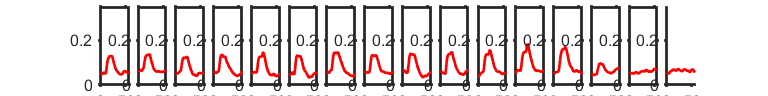

% load traces from 0, 20, 40


% played to L ear unless otherwise noted

 tmem1cko0db = load('370_3_0dBMOCO.mat'); % P21 
 tmem2cko0db = load('359_2_0dB.mat'); % P15?
 tmem3cko0db = load('365_2_0dB.mat'); % P18
 tmem4cko0db = load('408_1_0dB.mat'); % P16
 tmem5cko0db = load('405_1_0dB.mat'); % P16
  tmem6cko0db = load('405_3_0dB.mat'); % P16
  tmem7cko0db = load('405_5_0dB.mat'); % P16
time = [1:1:length(tmem2cko0db.avgAC)];

for i = 1:16
    avgcko0db(i,:) = mean([tmem1cko0db.avgAC(i,1:56);tmem2cko0db.avgAC(i,:);tmem3cko0db.avgAC(i,:);tmem4cko0db.avgAC(i,1:56);tmem5cko0db.avgAC(i,1:56);tmem6cko0db.avgAC(i,1:56);tmem7cko0db.avgAC(i,1:56);],1);
    stdcko0db(i,:) = std([tmem1cko0db.avgAC(i,1:56);tmem2cko0db.avgAC(i,:);tmem3cko0db.avgAC(i,:);tmem4cko0db.avgAC(i,1:56);tmem5cko0db.avgAC(i,1:56);tmem6cko0db.avgAC(i,1:56);tmem7cko0db.avgAC(i,1:56);],1)/sqrt(7);
end

figure
for i = 1:16
    hold on
    subplot(1,16,i);
    plot(avgcko0db(i,:),'r','LineWidth',2)
    ylim([0 0.35])
end
figQuality(gcf,gca,[8 1])

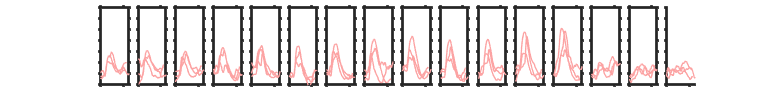


% controls - fl/fl (couple of Cx26 controls to increase n)
con1db0 = load('370_2_0dB.mat'); % fl/fl, P21
con2db0 = load('352_3_0dB.mat'); % fl/fl, P15? 
con3db0 = load('405_2_0dB.mat'); % fl/fl, P16
con4db0 = load('374_3_0dB.mat'); % fl/fl

% con4db0 = load('338_3_0dB.mat'); 
% con5db0 = load('338_1_0dB.mat'); %fl/fl
% con6db0 = load('306_1_0dB.mat'); % fl/fl
% con7db0 = load('346_1_0dB.mat'); % fl/fl

avgCon0db = [];
for i = 1:16
    avgCon0db(i,:) = mean([con1db0.avgAC(i,1:56);con2db0.avgAC(i,:);con3db0.avgAC(i,1:56);con4db0.avgAC(i,1:56);],1);
    stdCon0db(i,:) = std([con1db0.avgAC(i,1:56);con2db0.avgAC(i,:);con3db0.avgAC(i,1:56);con4db0.avgAC(i,1:56);],1)/sqrt(4);
end
% plot of all traces
l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:16
    subplot(1,16,i);
    plot(tmem1cko0db.avgAC(i,:),'Color',l_red,'LineWidth',1)
    
    plot(tmem2cko0db.avgAC(i,:),'Color',l_red,'LineWidth',1)
    hold on
    plot(tmem3cko0db.avgAC(i,:),'Color',l_red,'LineWidth',1)
    plot(tmem4cko0db.avgAC(i,:),'Color',l_red,'LineWidth',1)
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[8 1])

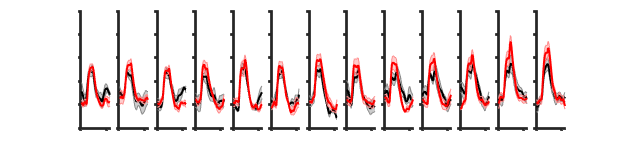


% standard error 
figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
    c.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

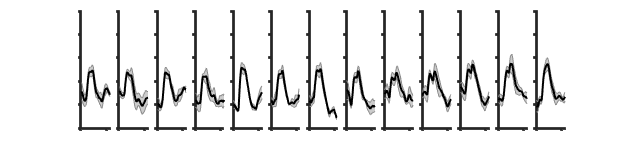

%print(gcf,'-dpdf')

% plot separately

figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
    c.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

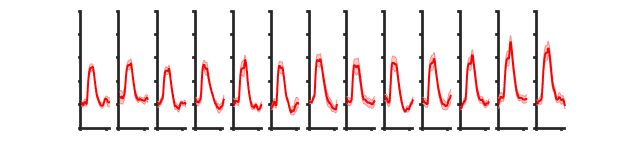

%print(gcf,'-dpdf')

figure
for i = 1:13
    subplot(1,13,i);
     c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

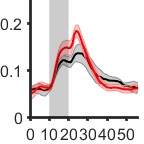

%print(gcf,'-dpdf')

figure
for i = 12
    %subplot(1,13,i);
    c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
    c.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
     patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    %yticklabels([]);
    xticklabels([0 10 20 30 40 50]);
end
figQuality(gcf,gca,[1.5 1.5])

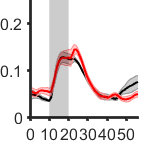

%print(gcf,'-dpdf')

figure
for i = 5
    %subplot(1,13,i);
    c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
    c.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
     patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    %yticklabels([]);
    xticklabels([0 10 20 30 40 50]);
end
figQuality(gcf,gca,[1.5 1.5])

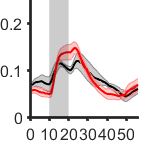

%print(gcf,'-dpdf')

figure
for i = 10
    %subplot(1,13,i);
    c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
    c.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
     patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    %yticklabels([]);
    xticklabels([0 10 20 30 40 50]);
end
figQuality(gcf,gca,[1.5 1.5])

%print(gcf,'-dpdf')



% 40 dB 
% played to L ear unless otherwise noted
% 
% cx261cko40db = load('369_4_40dB.mat'); 
% cx262cko40db = load('369_2_40dB.mat'); 
% cx263cko40db = load('369_1_40dB.mat'); 
% cx264cko40db = load('355_3_40dB.mat'); 
% cx265cko40db = load('375_1_40dB.mat'); 
% 
% con1db40 = load('369_5_40dB.mat'); %fl/fl
% con2db40 = load('368_3_40dB.mat'); %fl/fl
% con3db40 = load('368_1_40dB.mat'); %fl/fl
% con4db40 = load('355_2_40dB.mat'); %cre+ het
% %con5db0 = load('342_2_0dB.mat');
% 
% time = [1:1:length(cx264cko40db.avgAC)];
% 
% for i = 1:16
%     avgcko40db(i,:) = mean([cx261cko40db.avgAC(i,1:56);cx262cko40db.avgAC(i,1:56);cx263cko40db.avgAC(i,1:56);cx264cko40db.avgAC(i,:);cx265cko40db.avgAC(i,1:56)],1);
%     stdcko40db(i,:) = std([cx261cko40db.avgAC(i,1:56);cx262cko40db.avgAC(i,1:56);cx263cko40db.avgAC(i,1:56);cx264cko40db.avgAC(i,:);cx265cko40db.avgAC(i,1:56)],1);
% end
% 
% for i = 1:16
%     avgCon40db(i,:) = mean([con1db40.avgAC(i,1:56);con2db40.avgAC(i,1:56);con3db40.avgAC(i,1:56);con4db40.avgAC(i,:)],1);
%     stdCon40db(i,:) = std([con1db40.avgAC(i,1:56);con2db40.avgAC(i,1:56);con3db40.avgAC(i,1:56);con4db40.avgAC(i,:)],1);
% end
% 
% l_grey = [0.7 0.7 0.7];
% l_red = [252/255 163/255 163/255];
% 
% 
% figure
% for i = 1:16
%     subplot(1,16,i);
%   % c = shadedErrorBar(time,avgCon40db(i,:),stdCon40db(i,:));
%    c.mainLine.LineWidth = 1.5;
%     hold on
% 
%    c1 = shadedErrorBar(time,avgcko40db(i,:),stdcko40db(i,:),'lineprops','r');
%    c1.mainLine.LineWidth = 1.5;
%     ylim([0 0.5])
%     yticklabels([]);
%     xticklabels([]);
% end
% figQuality(gcf,gca,[6.5 1.5])
% %print(gcf,'-dpdf')

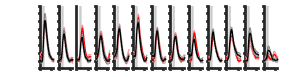

% P13 - P14 sound evoked AC responses
% 0 db attenuation

con1db0 = load('427_1_0dB.mat'); % P13
con2db0 = load('427_3_0dB.mat'); % P13
con3db0 = load('383_1_0dB.mat'); % P14
con4db0 = load('437_1_0dB.mat'); % P13
con5db0 = load('441_1_0dB.mat'); % P13
con6db0 = load('500_2_0dB.mat'); %P13

cko1db0 = load('427_2_0dB.mat'); % P13
cko2db0 = load('437_2_0dB.mat'); % P13
cko3db0 = load('443_2_0dB.mat'); % P13
cko4db0 = load('437_3_0dB.mat'); % P13 % very high thresholds. exclude? 
cko5db0 = load('500_1_0dB.mat'); %p13 
cko6db0 = load('502_3_0dB.mat'); %P13


 avgCon0db = [];
for i = 1:16
    avgCon0db(i,:) = mean([con1db0.avgAC(i,:);con2db0.avgAC(i,:);con3db0.avgAC(i,:);con4db0.avgAC(i,:);con5db0.avgAC(i,:);con6db0.avgAC(i,:)],1);
    stdCon0db(i,:) = std([con1db0.avgAC(i,:);con2db0.avgAC(i,:);con3db0.avgAC(i,:);con4db0.avgAC(i,:);con5db0.avgAC(i,:);con6db0.avgAC(i,:)],1)/sqrt(6);
end

for i = 1:16
    avgcko0db(i,:) = mean([cko1db0.avgAC(i,:);cko2db0.avgAC(i,:);cko3db0.avgAC(i,:);cko4db0.avgAC(i,:);cko5db0.avgAC(i,:);cko6db0.avgAC(i,:)],1);
    stdcko0db(i,:) = std([cko1db0.avgAC(i,:);cko2db0.avgAC(i,:);cko3db0.avgAC(i,:);cko4db0.avgAC(i,:);cko5db0.avgAC(i,:);cko6db0.avgAC(i,:)],1)/sqrt(6);
end

time = [1:1:length(con2db0.avgAC)];
figure
for i = 1:13
    subplot(1,13,i);
   c1 = shadedErrorBar(time,avgcko0db(i,:)-min(avgcko0db(i,:))+0.05,stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    c = shadedErrorBar(time,avgCon0db(i,:)-min(avgCon0db(i,:))+0.05,stdCon0db(i,:));
    c.mainLine.LineWidth = 1;
    
  
    ylim([0 0.4])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])
print(gcf,'-dpdf')

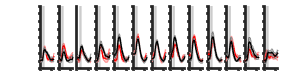


% 20 db atten
con1db20 = load('427_1_20dB.mat'); % P13
con2db20 = load('427_3_20dB.mat'); % P13
con3db20 = load('383_1_20dB.mat'); % P14
con4db20 = load('437_1_20dB.mat'); % P13
con5db20 = load('441_1_20dB.mat'); % P13
con6db20 = load('500_2_20dB.mat'); % P13

cko1db20 = load('427_2_20dB.mat'); % P13
cko2db20 = load('437_2_20dB.mat'); % P13
cko3db20 = load('443_2_20dBmoco.mat'); % P13
cko4db20 = load('437_3_20dB.mat'); %P13 % very high thresholds. exclude? 
cko5db20 = load('500_1_20dB.mat');
cko6db20 = load('502_3_20dB.mat');

 avgCon0db = [];
for i = 1:16
    avgCon20db(i,:) = mean([con1db20.avgAC(i,:);con2db20.avgAC(i,:);con3db20.avgAC(i,:);con4db20.avgAC(i,:);con5db20.avgAC(i,:);con6db20.avgAC(i,:)],1);
    stdCon20db(i,:) = std([con1db20.avgAC(i,:);con2db20.avgAC(i,:);con3db20.avgAC(i,:);con4db20.avgAC(i,:);con5db20.avgAC(i,:);con6db20.avgAC(i,:)],1)/sqrt(6);
end
for i = 1:16
    avgcko20db(i,:) = mean([cko1db20.avgAC(i,:);cko2db20.avgAC(i,:);cko3db20.avgAC(i,:);cko4db20.avgAC(i,:);cko5db20.avgAC(i,:);cko6db20.avgAC(i,:)],1);
    stdcko20db(i,:) = std([cko1db20.avgAC(i,:);cko2db20.avgAC(i,:);cko3db20.avgAC(i,:);cko4db20.avgAC(i,:);cko5db20.avgAC(i,:);cko6db20.avgAC(i,:)],1)/sqrt(6);
end

time = [1:1:length(con2db20.avgAC)];
figure
for i = 1:13
    subplot(1,13,i);
        c1 = shadedErrorBar(time,avgcko20db(i,:)-min(avgcko20db(i,:))+0.05,stdcko20db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
        hold on
    c = shadedErrorBar(time,avgCon20db(i,:)-min(avgCon20db(i,:))+0.05,stdCon20db(i,:));
    c.mainLine.LineWidth = 1;


    ylim([0 0.4])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])
print(gcf,'-dpdf')

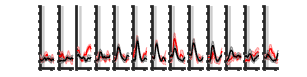


% 40 db atten

 con1db40 = load('427_1_40dB.mat'); % P13
 con2db40 = load('427_3_40dB.mat'); % P13
con3db40 = load('383_1_40dB.mat'); % P14
con4db40 = load('437_1_40dB.mat'); % P13
con5db40 = load('441_1_40dB.mat'); %P13
con6db40 = load('500_2_40dB.mat'); % P13

cko1db40 = load('427_2_40dB.mat'); % P13
cko2db40 = load('437_2_40dB.mat'); % P13
cko3db40 = load('443_2_40dB.mat'); % P13
cko4db40 = load('437_3_40dB.mat'); %P13 % very high thresholds. exclude? 
cko5db40 = load('500_1_40dB.mat');

 avgCon40db = [];
for i = 1:16
    avgCon40db(i,:) = mean([con1db40.avgAC(i,:);con2db40.avgAC(i,:);con3db40.avgAC(i,:);con4db40.avgAC(i,:);con5db40.avgAC(i,:);con6db40.avgAC(i,:)],1);
    stdCon40db(i,:) = std([con1db40.avgAC(i,:);con2db40.avgAC(i,:);con3db40.avgAC(i,:);con4db40.avgAC(i,:);con5db40.avgAC(i,:);con6db40.avgAC(i,:)],1)/sqrt(6);
end
for i = 1:16
    avgcko40db(i,:) = mean([cko1db40.avgAC(i,:);cko2db40.avgAC(i,:);cko3db40.avgAC(i,:);cko4db40.avgAC(i,:);cko5db40.avgAC(i,:)],1);
    stdcko40db(i,:) = std([cko1db40.avgAC(i,:);cko2db40.avgAC(i,:);cko3db40.avgAC(i,:);cko4db40.avgAC(i,:);cko5db40.avgAC(i,:)],1)/sqrt(5);
end

time = [1:1:length(con2db40.avgAC)];
figure
for i = 1:13
    subplot(1,13,i);
        c1 = shadedErrorBar(time,avgcko40db(i,:)-min(avgcko40db(i,:))+0.05,stdcko40db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    c = shadedErrorBar(time,avgCon40db(i,:)-min(avgCon40db(i,:))+0.05,stdCon40db(i,:));
    c.mainLine.LineWidth = 1;
    ylim([0 0.4])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])
print(gcf,'-dpdf')

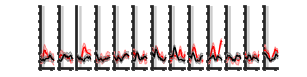


% 60 dB atten P13-P14 AC

con1db60 = load('427_1_60dB.mat'); % P13
con2db60 = load('427_3_60dB.mat'); % P13
con3db60 = load('383_1_60dB.mat'); % P14
con4db60 = load('437_1_60dB.mat'); % P13
con5db60 = load('441_1_60dB.mat'); %P13
con6db60 = load('500_2_60dB.mat'); %p13

cko1db60 = load('427_2_60dB.mat'); % P13
cko2db60 = load('437_2_60dB.mat'); % P13
cko4db60 = load('437_3_60dB.mat'); %P13 % very high thresholds. exclude? 
cko5db60 = load('500_1_60dB.mat');

 avgCon40db = [];
for i = 1:16
    avgCon60db(i,:) = mean([con1db60.avgAC(i,:);con2db60.avgAC(i,:);con3db60.avgAC(i,:);con4db60.avgAC(i,:);con5db60.avgAC(i,:);con6db60.avgAC(i,:)],1);
    stdCon60db(i,:) = std([con1db60.avgAC(i,:);con2db60.avgAC(i,:);con3db60.avgAC(i,:);con4db60.avgAC(i,:);con5db60.avgAC(i,:);con6db60.avgAC(i,:)],1)/sqrt(6);
end
for i = 1:16
    avgcko60db(i,:) = mean([cko1db60.avgAC(i,:);cko2db60.avgAC(i,:);cko4db60.avgAC(i,:);cko5db60.avgAC(i,:)],1);
    stdcko60db(i,:) = std([cko1db60.avgAC(i,:);cko2db60.avgAC(i,:);cko4db60.avgAC(i,:);cko5db60.avgAC(i,:)],1)/sqrt(4);
end

time = [1:1:length(con2db60.avgAC)];
figure
for i = 1:13
    subplot(1,13,i);
        c1 = shadedErrorBar(time,avgcko60db(i,:)-min(avgcko60db(i,:))+0.05,stdcko60db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    c = shadedErrorBar(time,avgCon60db(i,:)-min(avgCon60db(i,:))+0.05,stdCon60db(i,:));
    c.mainLine.LineWidth = 1;
    ylim([0 0.4])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])

%print(gcf,'-dpdf')



